clc
clear

% read txt file as a timetable into MATLAB
path = uigetdir %%Choose Dir for new data

path = 'C:\Users\luxtu\Desktop\Open-BCI-\OBCILiveTestingData'

data = readtimetable(uigetfile)

data = 67870×15 timetable
     Timestamp_Formatted_      SampleIndex    EXGChannel0    EXGChannel1    EXGChannel2    EXGChannel3    AccelChannel0    AccelChannel1    AccelChannel2    Other    Other_1    Other_2    Other_3    Other_4    Timestamp     Other_5
    _______________________    ___________    ___________    ___________    ___________    ___________    _____________    _____________    _____________    _____    _______    _______    _______    _______    __________

data = removevars(data,{'Other','Other_1','Other_2','Other_3','Other_4','Other_5'})

data = 67870×9 timetable
     Timestamp_Formatted_      SampleIndex    EXGChannel0    EXGChannel1    EXGChannel2    EXGChannel3    AccelChannel0    AccelChannel1    AccelChannel2    Timestamp 
    _______________________    ___________    ___________    ___________    ___________    ___________    _____________    _____________    _____________    __________

    2022-03-07 14:12:19.194         2            3.0518         93.254        -145.81         40.664         -0.768              0                0          1.6467e+09
    2022-03-07 14:12:19.194         2           -10.906        -78.572        -365.04        -25

% Separate date and time from datetime variable
t = datetime(data.Timestamp_Formatted_);
v = datevec(t);
date = datetime(v(:,1:3));
time = duration(v(:,4:end));

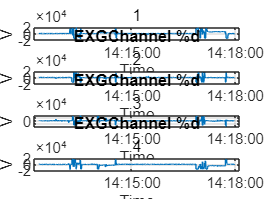

% plot EXGChannel data with time 

EEG_data = [data.EXGChannel0 data.EXGChannel1 data.EXGChannel2 data.EXGChannel3];

i = 1;
for i = 1:4
    subplot(4,1,i)
    plot_data = EEG_data(:,i);
    plot(time,plot_data)
    grid on 
    title('EXGChannel %d',i)
    xlabel('Time')
    ylabel('V')
    i = i + 1;
end

spectrogram

'spectrogram' requires Signal Processing Toolbox.